# Workflow DES + Agua

**1. Importar los datos de viscosidad**

Visc_Mal=readtable("TFM\DATASET_TFM_DES_H2O.xlsx","Sheet","Visc_Maline","VariableNamingRule","preserve")

Visc_Mal = 172×11 table
        DES            Set Type        Condition      Mixture       Mass_percent_Water    Mass_percent_DES    Temperature(K)    Viscosity(Pa.s)    Viscosity(cP)         Reference          DES mole fraction
    ___________    ________________    _________    ____________    __________________    ________________    ______________    _______________    _____________    ____________________    _________________

    {'ChCl-MA'}    {'Experimental'}     {'QCM'}     {'Pure DES'}            0                    1                303.01             0.04766           47.66        {'(Barzinjy, 2016)'}     

Gráfica de datos de viscosidad

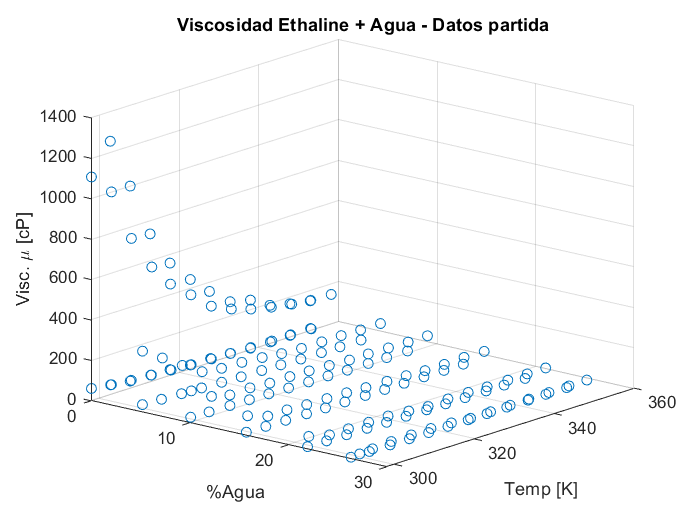

Masa_H2O_Mal=Visc_Mal.Mass_percent_Water*100;
Temp_Mal=Visc_Mal.("Temperature(K)");
Mu_Mal=Visc_Mal.("Viscosity(cP)");
figure, plot3(Masa_H2O_Mal,Temp_Mal,Mu_Mal,'o');
title('Viscosidad Ethaline + Agua - Datos partida'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Visc. \mu [cP]'),
view([40 20])

**2. División Conjuntos de Datos Entrenamiento y Prueba**

Matriz de datos de entrenamiento (2 predictores, 1 respuesta).

data1=[Masa_H2O_Mal,Temp_Mal,Mu_Mal];
n=length(data1);
particion=cvpartition(n,'HoldOut',0.2) % Se separa un 20% de datos para prueba

particion = Hold-out cross validation partition
   NumObservations: 172
       NumTestSets: 1
         TrainSize: 138
          TestSize: 34

Datos de entrenamiento

idx_train=training(particion);
train_data_visc1=data1(idx_train,:)

train_data_visc1 = 	1.0e+03 *

         0    0.3030    0.0477
         0    0.3077    0.0357
         0    0.3129    0.0328
         0    0.3177    0.0298
         0    0.3279    0.0209
         0    0.3328    0.0149
         0    0.3429    0.0089
         0    0.3479    0.0119
         0    0.3529    0.0119
         0    0.3027    1.2540



Masa_H2O_Mal_train=train_data_visc1(:,1);
Temp_Mal_train=train_data_visc1(:,2);
Mu_Mal_train=train_data_visc1(:,3);

Datos de prueba

idx_test=test(particion);
test_data_visc1=data1(idx_test,:)

test_data_visc1 =          0  322.7943   20.8511
         0  337.8650    8.9362
         0  312.7159  732.7660
         0  332.7786  271.0638
         0  308.0286  739.8374
         0  328.0604  278.8618
         0  317.9754   26.2332
    5.1668  308.0286  167.8862
    5.1329  323.0525   88.2114
    5.0655  352.9889   59.7561



Masa_H2O_Mal_test=test_data_visc1(:,1);
Temp_Mal_test=test_data_visc1(:,2);
Mu_Mal_test=test_data_visc1(:,3);

**3. Regresión**

predictores_train=[Masa_H2O_Mal_train Temp_Mal_train];
regresion1 = fitlm(predictores_train,Mu_Mal_train)

regresion1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     1146.9      277.05     4.1396    6.0935e-05
    x1              -8.336      1.5685    -5.3145    4.3045e-07
    x2             -2.9343     0.84249    -3.4828    0.00066909


Number of observations: 138, Error degrees of freedom: 135
Root Mean Squared Error: 179
R-squared: 0.225,  Adjusted R-Squared: 0.214
F-statistic vs. constant model: 19.6, p-value = 3.32e-08

Ecuacion

coef1=table2array(regresion1.Coefficients(1,1));
coef2=table2array(regresion1.Coefficients(2,1));
coef3=table2array(regresion1.Coefficients(3,1));

fprintf('Ecuación')

Ecuación

fprintf('Viscosidad= %0.4f+(%0.4f)*%%Agua+(%0.4f)*Temperatura',coef1, coef2, coef3)

Viscosidad= 1146.8834+(-8.3360)*%Agua+(-2.9343)*Temperatura

fprintf('Rango de porcentaje: %0.2f %% - %0.2f %%', min(Masa_H2O_Mal_train),max(Masa_H2O_Mal_train))

Rango de porcentaje: 0.00 % - 27.26 %

fprintf('Rango de temperatura: %0.2f K - %0.2f K', min(Temp_Mal_train),max(Temp_Mal_train))

Rango de temperatura: 297.90 K - 358.11 K